# Paper2 Fig2

## Setting up WS

CurrentFolder = pwd
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2

addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))
S = load(sprintf('AllMFPixPara_Paper2TuneFig1%s.mat',DataPoint));
% get proportions of SCI spikes
C_SS_Pixel_Us = S.C_SS_Pixel_Us;
C_CS_Pixel_Us = S.C_CS_Pixel_Us;
C_IS_Pixel_Us = S.C_IS_Pixel_Us;
C_SC_Pixel_Us = S.C_SC_Pixel_Us;
C_CC_Pixel_Us = S.C_CC_Pixel_Us;
C_IC_Pixel_Us = S.C_IC_Pixel_Us;
C_SI_Pixel_Us = S.C_SI_Pixel_Us;
C_CI_Pixel_Us = S.C_CI_Pixel_Us;
C_II_Pixel_Us = S.C_II_Pixel_Us;
N_HC = S.N_HC; NPixX = S.NPixX; NPixY = S.NPixY;
FrSPixVec = S.FrSPixVec;
FrCPixVec = S.FrCPixVec;
FrIPixVec = S.FrIPixVec;

L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec);
L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec ;
L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec);
L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec ;
L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec);
L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec ;
end
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);

assigne vector of proportions

L4Ep = [L4SEp,L4CEp,L4IEp]; L4Ip = [L4SIp, L4CIp, L4IIp];
close all

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','Larger','LARGER'};
AngPrint = '15.0';

## 3. Set up initial conditions

N_HCOut = 4; NPixX = 10; NPixY = 10;

ICTestAll = cell(2,1);

Background

ICData = load([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang0.0.mat')]);
LDEbgIC = ICData.LDEEquv;
LDEbgIC.S(:) = 2.5;
LDEbgIC.C(:) = 8;
LDEbgIC.I(:) = 18; %16
ICTestAll{1} = LDEbgIC;

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

load('LDETracesV4D2_NewSmear_ang0.0.mat')
LDEICPart = ICData.LDEEquv;


LDEICPart = HCRot(LDEICPart,0,N_HCOut,NPixX,NPixY,0);
ICTestAll{2} = LDEICPart;
LDEOutAll = cell(size(ICTestAll));

load equiv

%PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
%LDEEquv = PlotUse.LDEEquv;
%LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

Hyperparameters of iterations

p = 0.33;% 1-p for the original input
EpocTest = 300;
ExportFlag = 'xn';

L2Diff_OneStepAll = zeros(length(ICTestAll),EpocTest+1);
DiffVecAll = zeros(length(ICTestAll),EpocTest+1,3*NPixY*NPixX);

AngleTestAll = [0 60]; % 0:7.5:22.5; % has to be multiples of 7.5
N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;

load the LDE libraries: only 

L4EmeshXAll = cell(size(DomList));
L4ImeshYAll = cell(size(DomList));
LDEFrfuncAll = cell(size(DomList));
for DomInd = 1:length(DomList)
    FuncTemp = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{DomInd}),...
        'LDEFrfunc','L4EmeshX','L4ImeshY');
    L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
    L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
    LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
end

## Make Fig 2

Fig2b

Fig2b = figure('Name','Fig2b','units','normalized','outerposition',[0,0,0.35,0.3]);
Panel1 = 1; Panel2 = 3;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.05 .05],[.15 .15],[.15 .15]);
DomInd = 1;
Celltype = {'S','C','I'};

plot 16 functions for S

LDEFrcell = LDEFrfuncAll{DomInd};
for CellT = 1:Panel1*Panel2
    axes(ha(CellT));
    s(CellT) = mesh(...
        L4EmeshXAll{DomInd}*L4Ep(CellT),L4ImeshYAll{DomInd}*L4Ip(CellT),...
        LDEFrcell.(Celltype{CellT}){1,1},'FaceAlpha','0.9');
    s(CellT).FaceColor = 'flat';
    s(CellT).EdgeColor = 'none';
    view(2)

           axis and labels

    colormap('jet')
    axis([0 max(L4EmeshXAll{DomInd}*L4Ep(CellT),[],'all') 0 max(L4ImeshYAll{DomInd}*L4Ip(CellT),[],'all')])
    xlabel(['n^{' Celltype{CellT} 'E} (sp/s)'],'FontSize',13)
    ylabel(['n^{' Celltype{CellT} 'I} (sp/s)'],'FontSize',13)
    title(['Local Responses: F^' Celltype{CellT}],'FontSize',13)
    
    % colorbar
    if mod(CellT,Panel2) == 0
        Pos1 = get(gca,'Position');
        cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.03 Pos1(2)  0.02  Pos1(4)]);
        caxis([0 250])
        title(cbr1,'sp/(s\cdotcell)','FontSize',11)
        %set(cbr1,'FontSize',13)        
    end
end


print fig

Save and Print

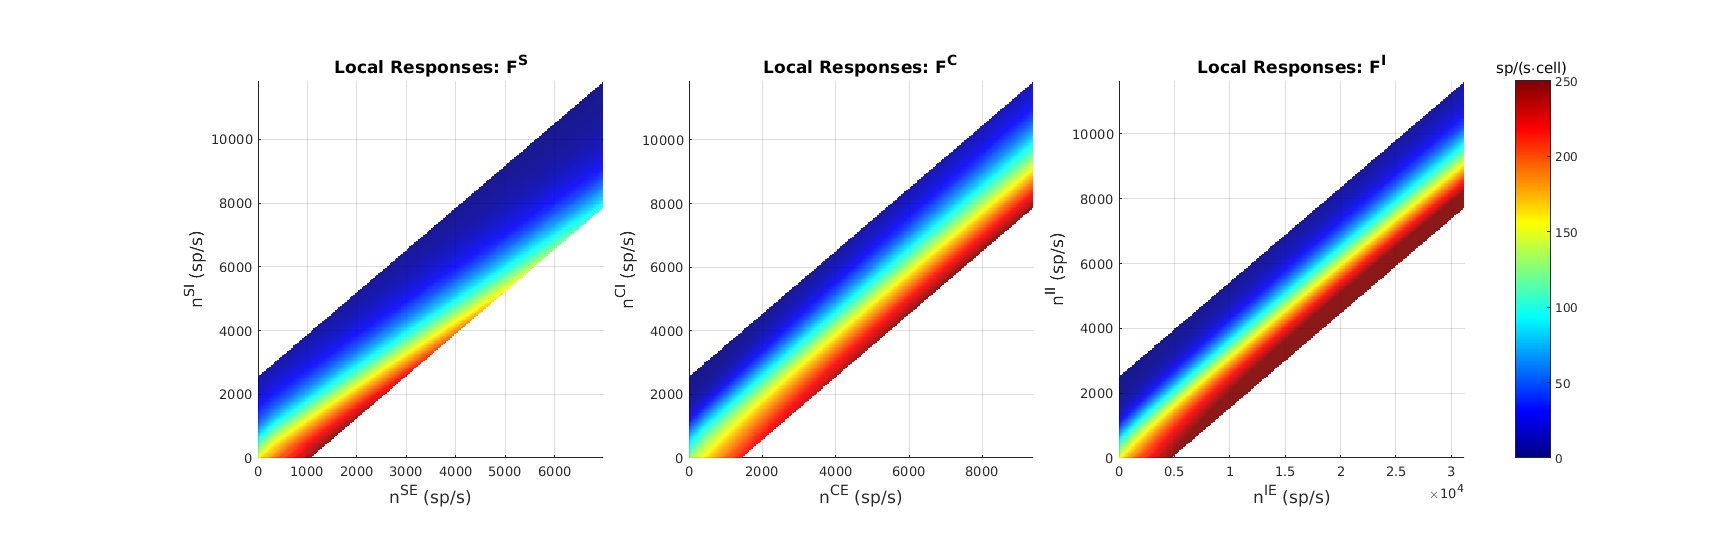

FigName2 = sprintf('Figure2b');
savefig(Fig2b,[FigurePaperPath FigName2 '.fig']);

Fig2b.PaperUnits = 'centimeters';
Fig2b.PaperSize = [32,16];
Fig2b.PaperOrientation = "landscape";
exportgraphics(Fig2b,[FigurePaperPath FigName2 '.pdf'],'Resolution',300)

Fig2A: struture of pixel and HC

Fig2a = figure('Name','Fig2a');
hold on
axis square
axis tight
% vertical and horizonal green lines
range = 0:20;
for linInd = 0:20
    plot(range,linInd*ones(size(range)),'g');
    plot(linInd*ones(size(range)),range,'g');
end

% the middle HC
for HClinInd = [5,15]
    plot(range,HClinInd*ones(size(range)),'k','LineWidth',3);
    plot(HClinInd*ones(size(range)),range,'k','LineWidth',3);
end

% ODs, oblique lines
for InterSec = -10:10:10
    plot(range,range + InterSec,'--b','LineWidth',1);
    plot(range,-range + InterSec + 20,'--b','LineWidth',1);
end

% OD orientations
plot(6.5*ones(size(8.5:11.5)),8.5:11.5,'r','LineWidth',8) % 0
plot(11:14,10*ones(size(11:14)),'r','LineWidth',8) % 90
ODObRange = 10-1.5/sqrt(2):0.01:10+1.5/sqrt(2);
plot(ODObRange, -ODObRange+23,'r','LineWidth',8 ) % 45
plot(ODObRange, ODObRange-3,'r','LineWidth',8 ) % 135

% fill an pixel
pixel = fill([11,12,12,11],[13,13,14,14],'g');
pixel.EdgeColor = [0,0.5,0];

% Say this is a pixel
annotation('textarrow',[0.7,0.58],[.935,0.71],'String','pixel','FontSize',12)

axis([3 17 3 17])
axis square
axis off
%axis tight

Save and Print

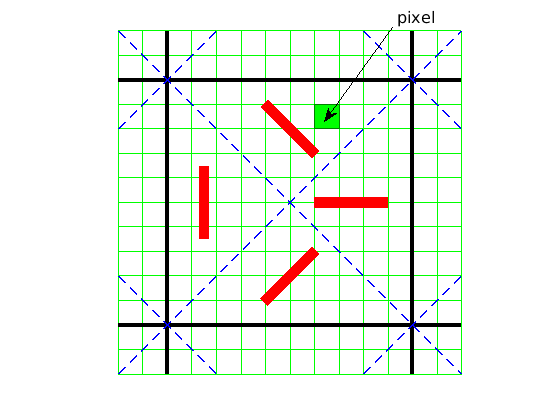

FigName1 = sprintf('Figure2a');
savefig(Fig2a,[FigurePaperPath FigName1 '.fig']);

Fig2a.PaperUnits = 'centimeters';
Fig2a.PaperSize = [16,16];
Fig2a.PaperOrientation = "landscape";
exportgraphics(Fig2a,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)

New Fig 2BCD

Fig2bcd = figure('Name','Fig2a');

B: theta-alpha

subplot(2,3,2)
hold on
plot(zeros(size(-3:3)),-3:3,'r','LineWidth',8) % 0
plot(-2:2,         -1*(-2:2),'k','LineWidth',4)
% plot the angle
theta = atan(2/-2) + pi;
ang = pi/2:0.01:theta;
r = 1;
arcxx = r*cos(ang); arcyy = r*sin(ang);
plot(arcxx, arcyy,'k')

text1 = text; clear text
text(0.3,r,'\leftarrow \theta - \alpha')
axis square
axis equal
axis off

C: sin curve

F2C = subplot(2,3,3);
ang = 0:0.01:pi;
fSLGN = @(x) (67.5+22.5*cos(2*x));
plot(ang, fSLGN(ang),'k')
xlabel('\theta - \alpha'); ylabel('$$n^{S\rm{LGN}_{hi}}_\alpha(\theta)/N^{S\rm{LGN}}$$','Interpreter','latex')
set(gca,'xtick',[0  pi/2  pi],'xticklabel',{'0','$$\pi/2$$','$$\pi$$'},...
    'ytick',[45 90]);
xlim([0 pi+0.001])
F2C.TickLabelInterpreter = 'latex';
set(gca,'FontSize',13)

D: LGN rates

angPlot = 0:30:90;
fSLGNAll = fSLGN(angPlot/180*pi);
xx = 0:300;
yy = zeros(size(xx));
for subId = 1:length(angPlot)
    subplot(2,length(angPlot),4+subId)
    yy(:) = fSLGNAll(subId);
    yy(126:250) = 90 - fSLGNAll(subId);
    plot(xx,yy)
    set(gca,'xtick',[0 125,250],'xticklabel',{'0','$$\tau/2$$','$$\tau$$'},...
        'TickLabelInterpreter','latex',...
        'ytick',[0 45,90])
    title(['\theta-\alpha = ',num2str(angPlot(subId)),char(176)])
    
    if subId == 1
        ylabel('LGN input rates')
    else
        set(gca,'YTick',{})
    end
    ylim([0 100])
    set(gca,'FontSize',13)
end

Save and Print

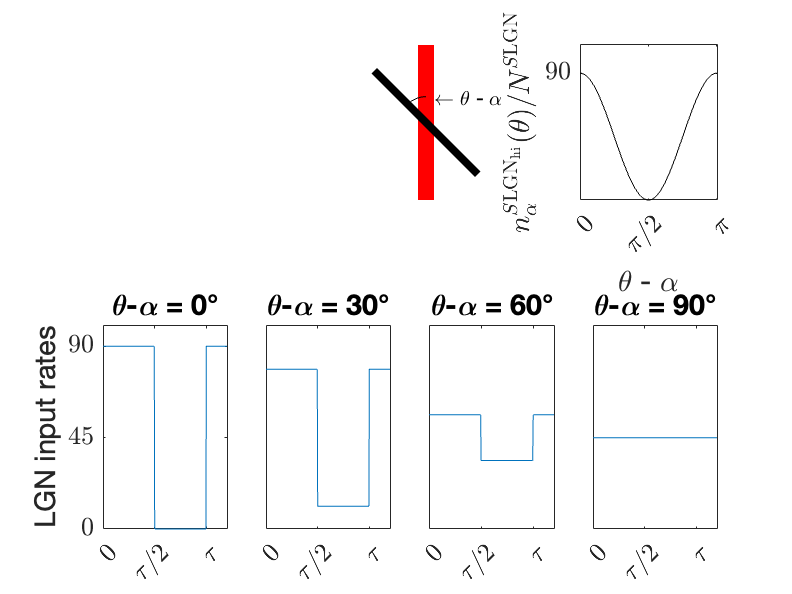

FigName3 = sprintf('Figure2bcd');
savefig(Fig2bcd,[FigurePaperPath FigName3 '.fig']);

Fig2bcd.PaperUnits = 'centimeters';
Fig2bcd.PaperSize = [28,16];
Fig2bcd.PaperOrientation = "landscape";
exportgraphics(Fig2bcd,[FigurePaperPath FigName3 '.pdf'],'Resolution',300)

Fig SA: Compare premodel and CG model connectivities

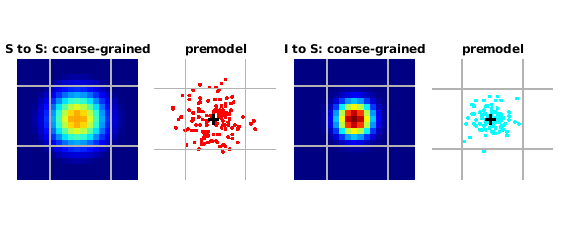

FigS1 = figure('Name','SI','units','inches','outerposition',[0,0,6,2.5]);
ha = tight_subplot(4,3,[.03 .03],[.03 .03],[.03 .03]);

% CG
axes(ha(1))
ShowField(C_SS_mean(435,:)',...
          1:PixNum,N_HC*NPixX,N_HC*NPixY,...
          'S to S: coarse-grained', [0 3.5])
colorbar off
axis([5 25 5 25])
axis off

axes(ha(3))
ShowField(C_SI_mean(435,:)',...
          1:PixNum,N_HC*NPixX,N_HC*NPixY,...
          'I to S: coarse-grained', [0 3.5])
colorbar off
axis([5 25 5 25])
axis off

% premodel
DataFolder11 = [CurrentFolder '/Data/Paper2_NetworkTuning/'];
addpath(DataFolder11)
if exist('CMatAll') ~= 1
load("DriveWkSp_SCSepa_Cconst_Conn.mat")
end
C_SS_Fix_Bd = CMatAll.C_EE_Fix_Bd(1:N_S,1:N_S) ;
C_SI_Fix_Bd = CMatAll.C_EI_Fix_Bd(1:N_S,:) ;

SX = 66; SY = 67;
SInd = find(NnS.X == SX & NnS.Y == SY);
PreSInd = find(C_SS_Fix_Bd(SInd,:));
PreIInd = find(C_SI_Fix_Bd(SInd,:));

axes(ha(2))
hold on
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
scatter(SX,SY,50,'k+','LineWidth',3)
grayColor = [.7 .7 .7];
for VerInd = 1:N_HC -1 % HC bounds
    plot(ones(length(0:n_S_HC*N_HC))*(VerInd*n_S_HC),0:n_S_HC*N_HC,'Color',grayColor,'LineWidth',1.5)%,1.5*n_S_HC/n_I_HC)
end
for HorInd = 1:N_HC -1
    plot(0:n_S_HC*N_HC,ones(length(0:n_S_HC*N_HC))*(HorInd*n_S_HC),'Color',grayColor,'LineWidth',1.5)%,1.5*n_S_HC/n_I_HC)
end
title('premodel')
axis([0.5*n_S_HC 2.5*n_S_HC 0.5*n_S_HC 2.5*n_S_HC])
axis square; axis off

axes(ha(4))
hold on
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'c.')
scatter(SX/n_S_HC*n_I_HC,SY/n_S_HC*n_I_HC,50,'k+','LineWidth',3)
grayColor = [.7 .7 .7];
for VerInd = 1:N_HC -1 % HC bounds
    plot(ones(length(0:n_I_HC*N_HC))*(VerInd*n_I_HC),0:n_I_HC*N_HC,'Color',grayColor,'LineWidth',1.5)
end
for HorInd = 1:N_HC -1
    plot(0:n_I_HC*N_HC,ones(length(0:n_I_HC*N_HC))*(HorInd*n_I_HC),'Color',grayColor,'LineWidth',1.5)
end
title('premodel')
axis([0.5*n_I_HC 2.5*n_I_HC 0.5*n_I_HC 2.5*n_I_HC])
axis square; axis off

Save and Print

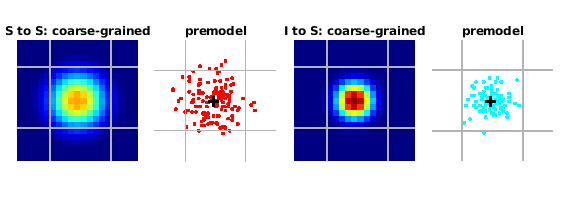

FigName4 = sprintf('FigureS1');
savefig(FigS1,[FigurePaperPath FigName4 '.fig']);

FigS1.PaperUnits = 'inches';
FigS1.PaperSize = [5.5,2];
FigS1.PaperOrientation = "landscape";
exportgraphics(FigS1,[FigurePaperPath FigName4 '.pdf'],'Resolution',300)